# Sensobed, review del código y proyecto

## Dudas:

- Muestreo: Se toma una frecuencia de muestreo de 200, mientras que en el informe indica 500Hz. Promedio,  ¿64 o 128?

- Filtros: Vemos que falta el filtro FPB de 0,5Hz (además no encontramos el sentido de este filtro). Obviando el último FPB, las frecuencias de corte de los filtros no coinciden con las del PDF (ver gráficas abajo).

- No sabemos por qué cuando muestra_h<100, actividad = 1.

- ¿Por qué el procesado se hace en serie y no en paralelo a la toma de muestras? En el pulso.

- ¿En el pulso cardíaco, por qué se eleva al cuadrado la muestra después de filtrar la primera vez?

- Puede haber casos en los que no se respeta la frecuencia de muestreo.

- Estabilidad del algoritmo para la respiración.

Cosas interesantes:

-   

   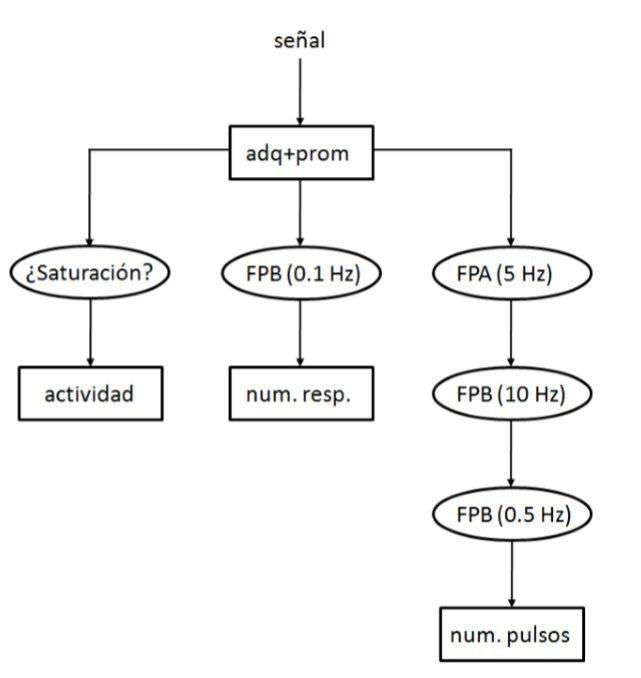

## Enlaces de interés

Raspberry:

- [Librería Scipy Signal](https://docs.scipy.org/doc/scipy/reference/signal.html) y [función sosfilter](https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.sosfilt.html#scipy.signal.sosfilt)

- [Librería Yodel](https://pypi.org/project/yodel/)

ESP32

## Estudio de filtros

% General
sample_rate = 200;

### Filtros para el ritmo cardíaco

**Filtro paso alta:**

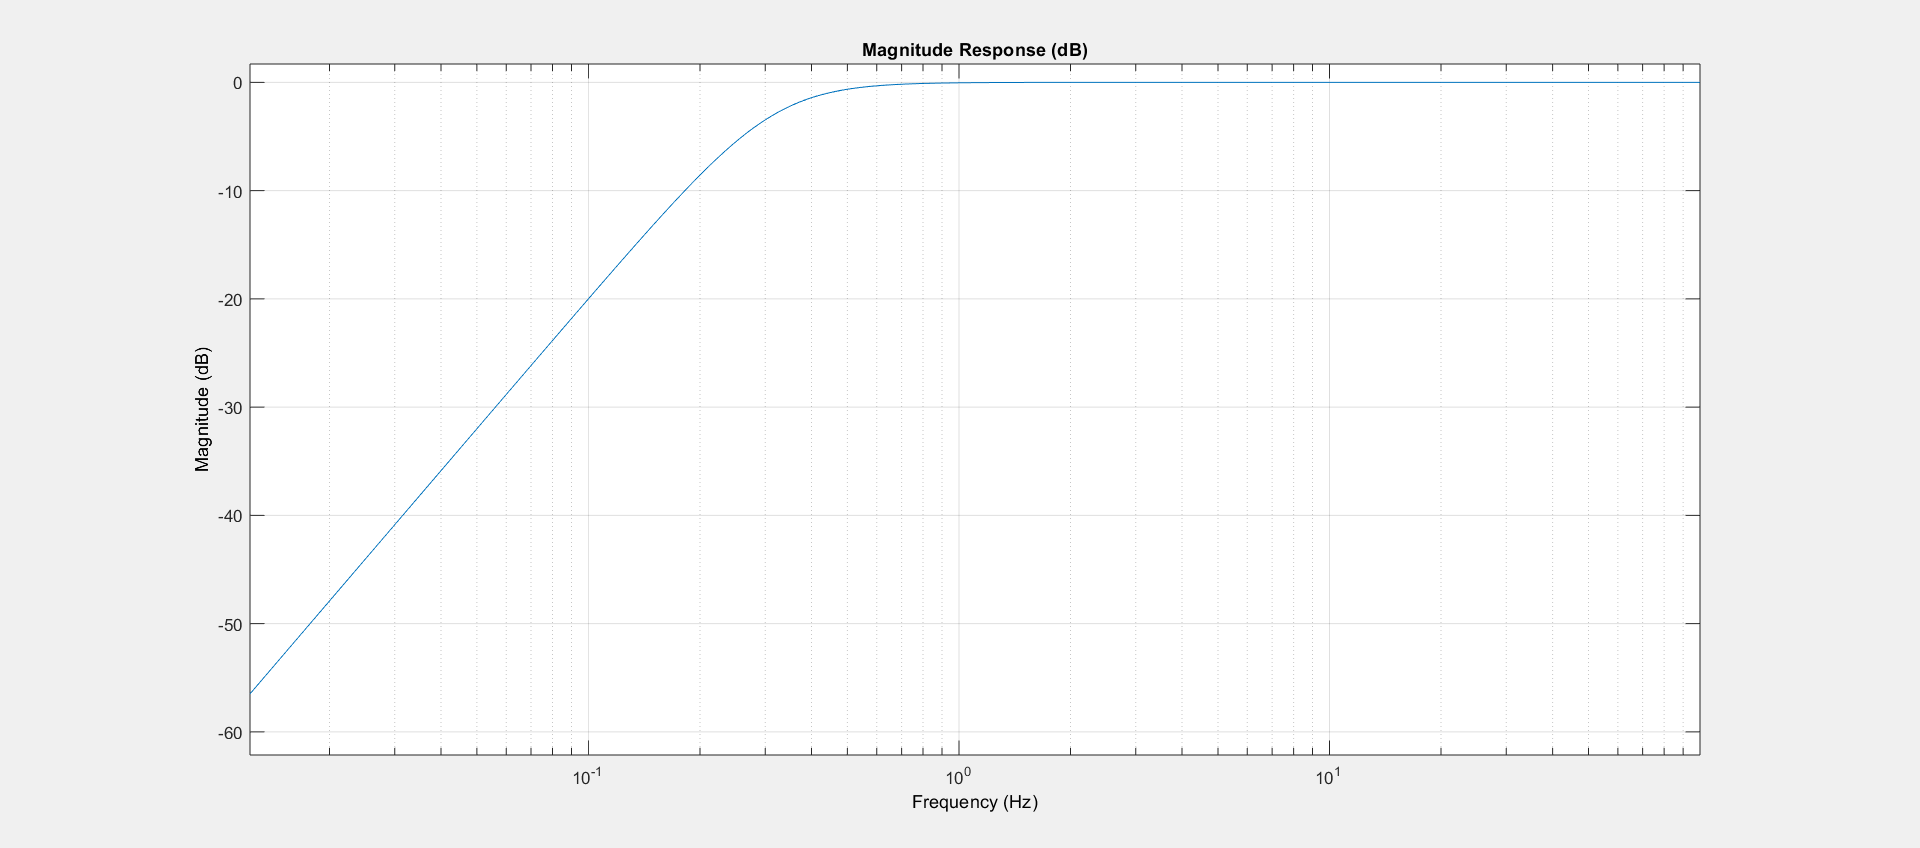

% Coeficientes paso alta
paso_alta_sos = [1, -2, 1,  1, -1.98598595723005, 0.986083473009604];
paso_alta_scale = 0.993017357559912;

biquad_hpf = dsp.BiquadFilter(paso_alta_sos,paso_alta_scale);
release(biquad_hpf)
figure(1)
h = fvtool(biquad_hpf,'Fs',sample_rate);
h.FrequencyScale = 'log';

**Filtro paso bajo:**

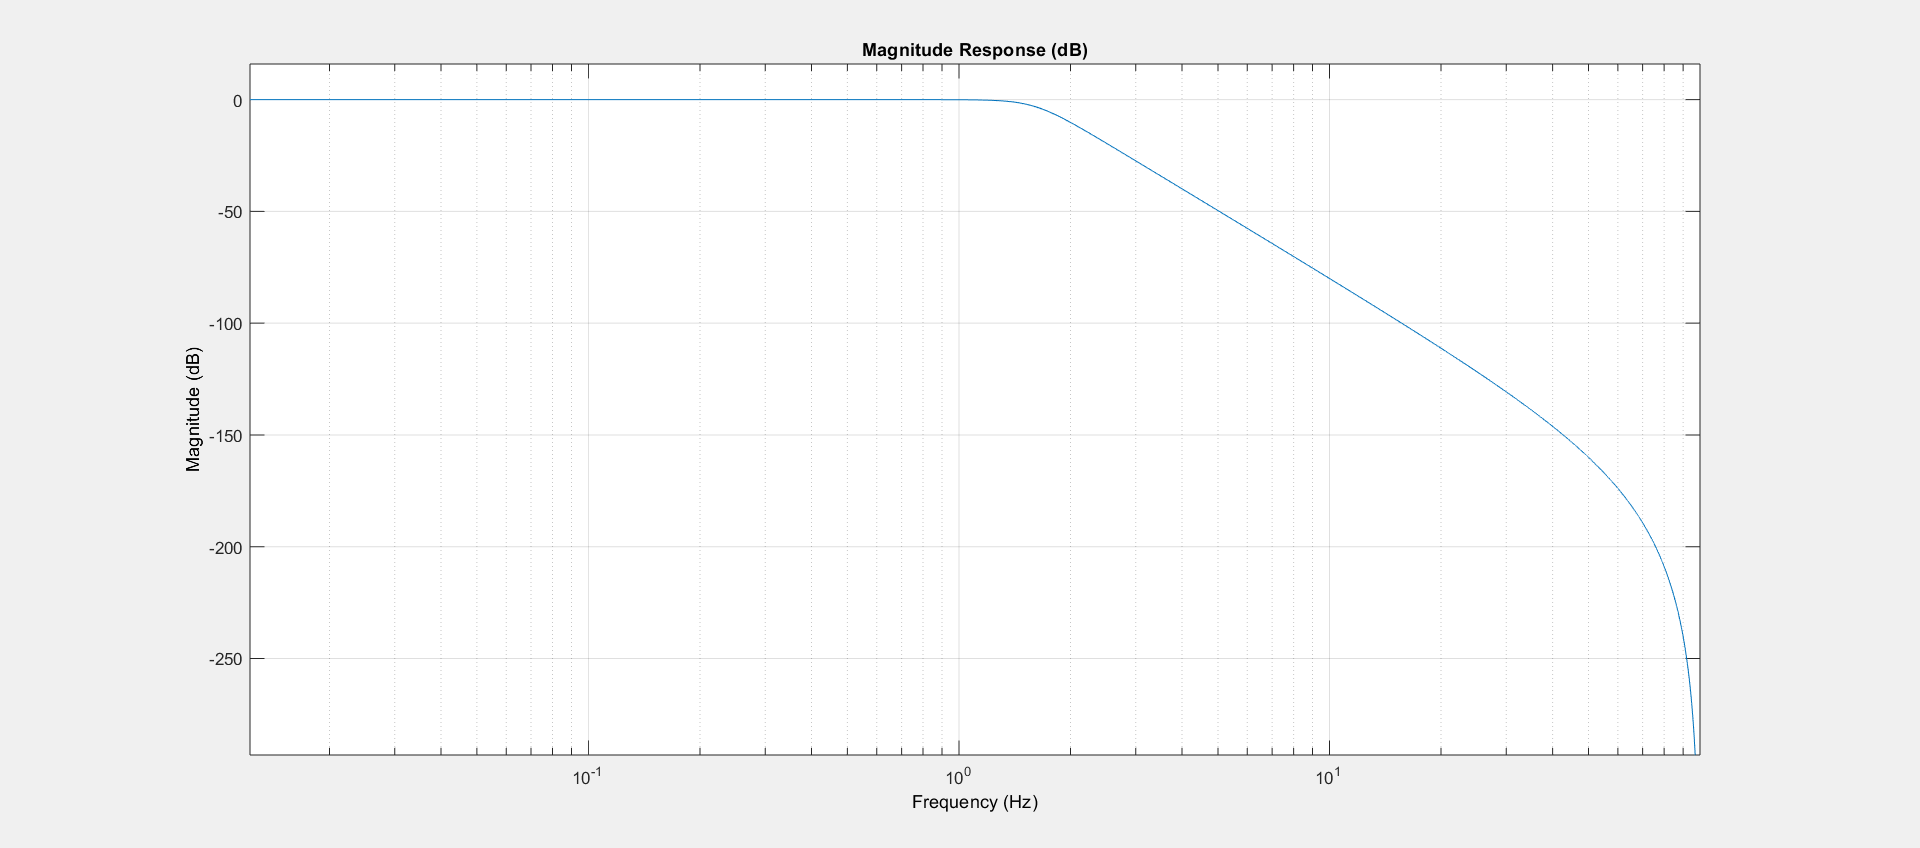

paso_baja_sos = [1, 2, 1,  1, -1.96698444058921, 0.969464886120290;
    1, 2, 1,  1, -1.91956461799301, 0.921985265243733;
    1, 1, 0,  1, -0.951024900504297,  0];
paso_baja_scale = [0.000620111382771082, 0.000605161812680899, 0.0244875497478514];
biquad_lpf = dsp.BiquadFilter(paso_baja_sos,paso_baja_scale);
figure(2)
g = fvtool(biquad_lpf,'Fs',sample_rate);
g.FrequencyScale = 'log';

fL_h = 0.316;   % (FPA) Frecuencia de corte inferior
fH_h = 1.597;   % (FPB) Frecuencia de corte superior

**Filtro paso banda (total) (este no terminar de cuadrar con el PDF)**

% Coeficientes de los filtros juntos, como si fuesen más secciones
total_sos = [1, -2, 1,  1, -1.98598595723005, 0.986083473009604;
            1, 2, 1,  1, -1.96698444058921, 0.969464886120290;
            1, 2, 1,  1, -1.91956461799301, 0.921985265243733;
            1, 1, 0,  1, -0.951024900504297,  0];
total_scale = [0.993017357559912 0.000620111382771082, 0.000605161812680899, 0.0244875497478514];
biquad = dsp.BiquadFilter(total_sos,total_scale);
figure(3)
h = fvtool(biquad,'Fs',sample_rate);
h.FrequencyScale = 'log';
BW_h = fH_h - fL_h;

### Filtro para la respiración (este si coincide con PDF)

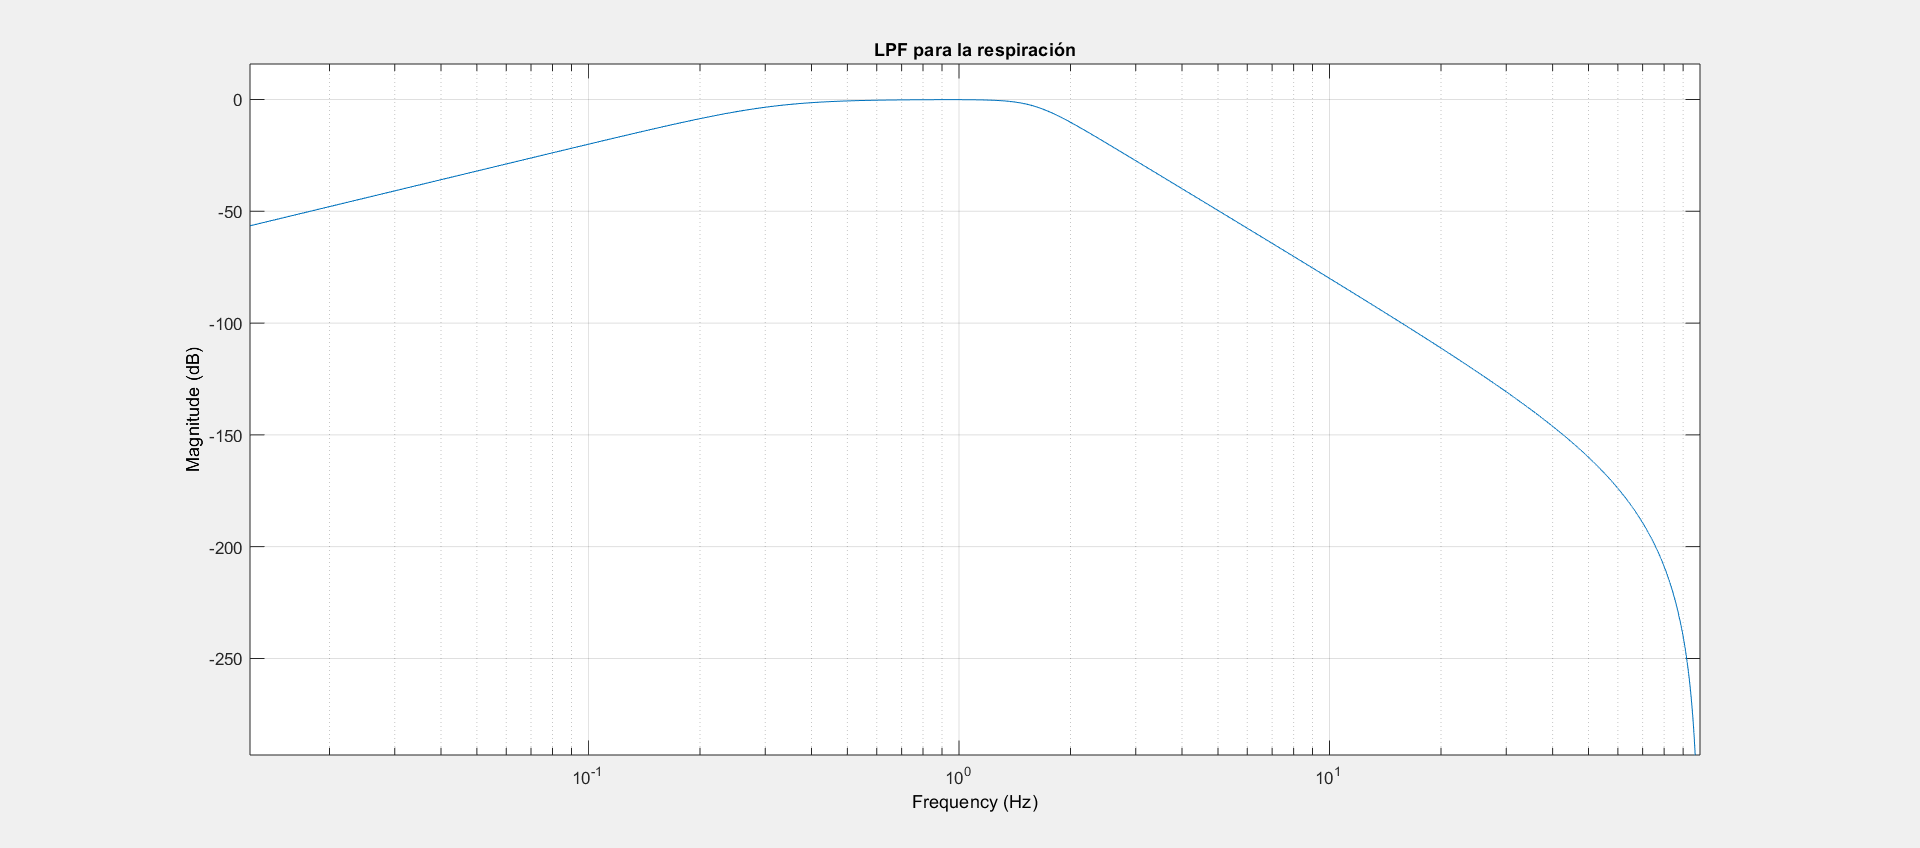

resp_sos = [1, 2, 1,  1, -1.99305810207877, 0.993105797090774;
            1, 1, 0,  1, -0.993105714885021, 0];
resp_scale = [0.0000119237530005953, 0.00344714255748968];

biquad_resp = dsp.BiquadFilter(resp_sos,resp_scale);
figure(4)
title('LPF para la respiración')

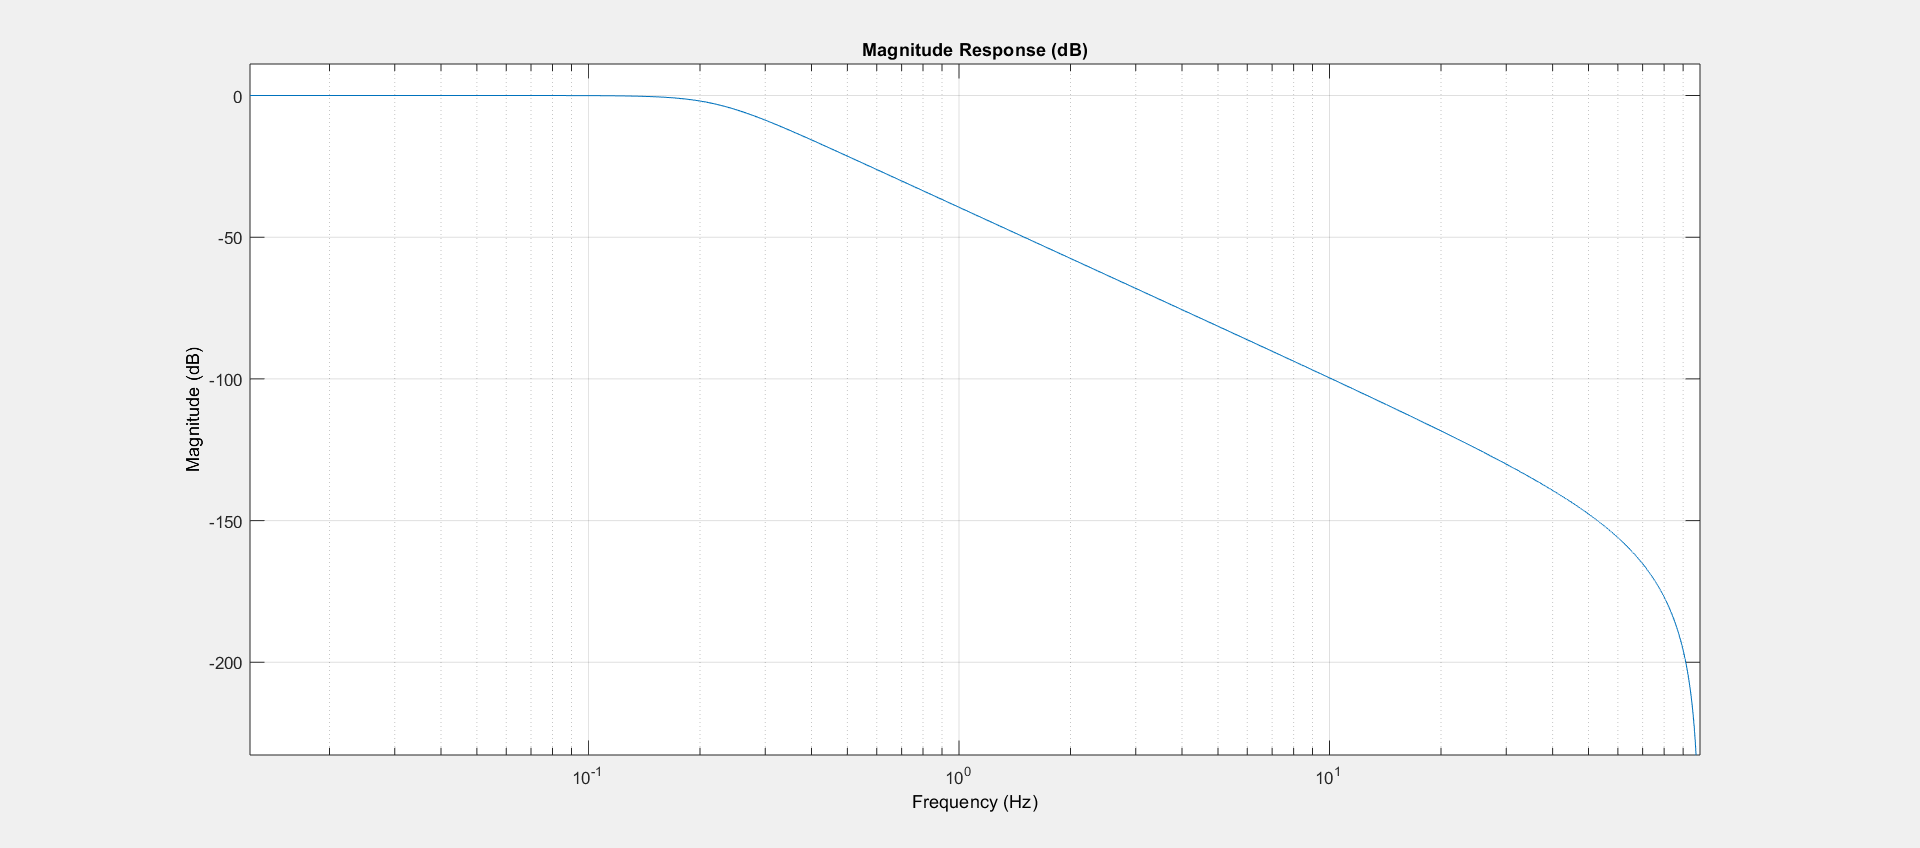

h = fvtool(biquad_resp,'Fs',sample_rate);
h.FrequencyScale = 'log';

fH_b = 0.22;
BW_b = fH_b;

### Implementación alternativa de filtrado

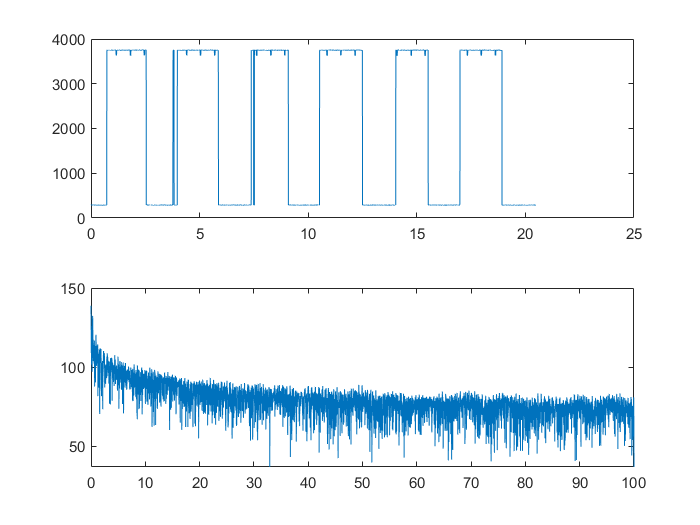

senal = csvread('signal.txt');
fs = 200;
Ts = 1/fs;
t = 0:Ts:(length(senal)-1)*Ts;
L = 2^16;
senal_f = fft(senal, L);
senal_f = senal_f(1:L/2);
f= fs*(0:(L/2-1))/L;

figure
subplot(211)
xlabel('Tiempo (s)')
ylabel('Amplitud')
title('Señal de la respiración en el tiempo')
plot(t,senal)

subplot(212)
xlabel('Frecuencia (s)')
ylabel('Amplitud')
title('Señal de la respiración en frecuencia')
plot(f,20*log10(abs(senal_f)))